% 1. 스크립트 초기화
clear all; 
close all; 
clc;

% 2. 처리할 파일 목록 정의
file_list = {
    'vitaflex_60_1st_2.mat',    % 1번
    'vitaflex_40_1st.mat',      % 2번
    'vitaflex_20_New_1st.mat',  % 3번
    'ecoflex_50_1st.mat',       % 4번
    'ecoflex_30_1st.mat',       % 5번
    'ecoflex_20_1st.mat'        % 6번
};

% 3. ★★★ Sensor_threshold_upper 값 하드코딩 ★★★
threshold_values = [
    2155,   % 1. vitaflex_60_1st_2.mat 용
    2145,   % 2. vitaflex_40_1st.mat 용
    2185,   % 3. vitaflex_20_New_1st.mat 용
    2140,   % 4. ecoflex_50_1st.mat 용
    2135,   % 5. ecoflex_30_1st.mat 용
    2135    % 6. ecoflex_20_1st.mat 용
];

% 3-1. ★★★ Legend 목록 정의 (문자열 배열) ★★★
Legend_list = [
    "vita-60",
    "vita-40",
    "vita-20",
    "eco-50",
    "eco-30",
    "eco-20"];

% 4. 6개의 그래프를 중첩해서 그릴 Figure 생성
figure;
hold on; % 이 Figure에 모든 그래프를 겹쳐 그립니다.

% 5. 파일 목록을 순회하며 데이터 처리 및 플로팅
for i = 1:length(file_list)
    
    current_file = file_list{i};
    fprintf('--- [%d/%d] 파일 처리 시작: %s ---\n', i, length(file_list), current_file);
    
    % (A) MAT 파일 불러오기
    load(current_file, 'out'); 

    % (B) 데이터 추출
    timeData = out.loadcellandpos.Time;
    LoadcellData = out.loadcellandpos.Data(:,1);
    DisplacementData = out.loadcellandpos.Data(:,2);
    TactilesensorData = out.loadcellandpos.Data(:,3);
    timeVector = seconds(timeData);
    
    data1 = timetable(timeVector, LoadcellData, 'VariableNames', {'LoadcellData'});
    data2 = timetable(timeVector, DisplacementData, 'VariableNames', {'DisplacementData'});
    data3 = timetable(timeVector, TactilesensorData, 'VariableNames', {'TactilesensorData'});
    
    % (C) 데이터 전처리
    Initial_force = mean(data1.LoadcellData(1:50));
    Force = (data1.LoadcellData - Initial_force) * -5;
    
    Initial_Displacement = mean(data2.DisplacementData(1:50));
    Displacement = (data2.DisplacementData - Initial_Displacement) * -2;
    
    Initial_Sensor = mean(data3.TactilesensorData(1:50));
    Sensor = data3.TactilesensorData;
    
    % (D) 하드코딩된 Threshold 값 가져오기
    Sensor_threshold_upper = threshold_values(i);
    fprintf('    적용된 Sensor_threshold_upper: %.1f\n', Sensor_threshold_upper);

    % (E) 센서 값 필터링
    Sensor_threshold_lower = Initial_Sensor;
    valid_indices1 = Sensor >= Sensor_threshold_lower;
    valid_indices2 = Sensor <= Sensor_threshold_upper;
    valid_indices = valid_indices1 & valid_indices2;
    
    Force_filtered = Force(valid_indices);
    Displacement_filtered = Displacement(valid_indices);
    Sensor_filtered = Sensor(valid_indices);
    timeVector_filtered = data1.timeVector(valid_indices);

    % (F) Force vs Sensor 그래프 그리기 (중첩)
    % plot 명령어에 'DisplayName' 속성을 추가하여 나중에 legend에서 사용하도록 합니다.
    plot(Sensor_filtered, Force_filtered, '-', 'LineWidth', 1.5, 'DisplayName', Legend_list(i));
    
    % ★★★ 루프 안의 legend(Legend_list(i)); 는 삭제합니다. ★★★
    
    % (G) 개별 파일 결과 출력
    p = polyfit(Sensor_filtered, Force_filtered, 1);
    stiffness = p(1);
    fprintf('    계산된 Gain: %.5f N/Value\n', stiffness);
    
    R = corrcoef(Sensor_filtered, Force_filtered);
    fprintf('    상관계수 (R): %.4f\n', R(1,2));
    fprintf('--------------------------------------------------\n');
    
    clear out; % 'out' 변수 클리어
end

--- [1/6] 파일 처리 시작: vitaflex_60_1st_2.mat ---


    적용된 Sensor_threshold_upper: 2155.0


    계산된 Gain: 0.00508 N/Value


    상관계수 (R): 0.9971


--------------------------------------------------


--- [2/6] 파일 처리 시작: vitaflex_40_1st.mat ---


    적용된 Sensor_threshold_upper: 2145.0


    계산된 Gain: 0.00574 N/Value


    상관계수 (R): 0.9993


--------------------------------------------------


--- [3/6] 파일 처리 시작: vitaflex_20_New_1st.mat ---


    적용된 Sensor_threshold_upper: 2185.0


    계산된 Gain: 0.00513 N/Value


    상관계수 (R): 0.9922


--------------------------------------------------


--- [4/6] 파일 처리 시작: ecoflex_50_1st.mat ---


    적용된 Sensor_threshold_upper: 2140.0


    계산된 Gain: 0.00537 N/Value


    상관계수 (R): 0.9995


--------------------------------------------------


--- [5/6] 파일 처리 시작: ecoflex_30_1st.mat ---


    적용된 Sensor_threshold_upper: 2135.0


    계산된 Gain: 0.00491 N/Value


    상관계수 (R): 0.9991


--------------------------------------------------


--- [6/6] 파일 처리 시작: ecoflex_20_1st.mat ---


    적용된 Sensor_threshold_upper: 2135.0


    계산된 Gain: 0.00432 N/Value


    상관계수 (R): 0.9991


--------------------------------------------------


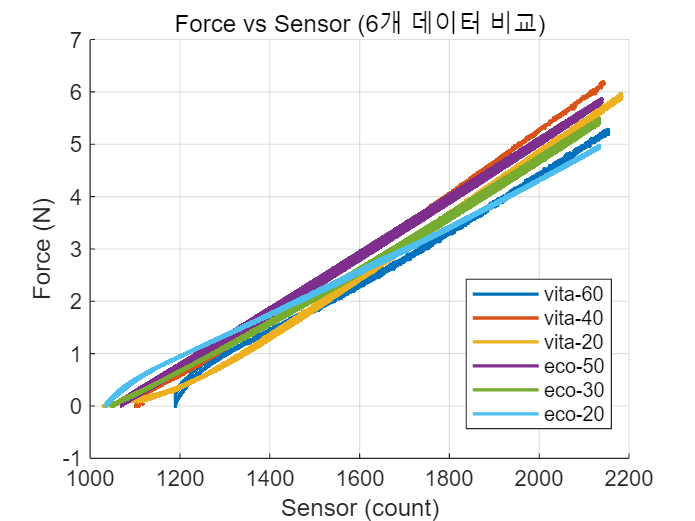



% 6. 최종 그래프 설정
hold off; % 그래프 중첩 종료
xlabel('Sensor (count)');
ylabel('Force (N)');
title('Force vs Sensor (6개 데이터 비교)');
grid on;

% ★★★ 루프가 끝난 후, DisplayName 속성을 사용하여 legend를 단 한 번 호출합니다. ★★★
legend('Location', 'best'); 


fprintf('\n★★★ 6개 파일의 그래프 작성이 완료되었습니다. ★★★\n');


★★★ 6개 파일의 그래프 작성이 완료되었습니다. ★★★
